# Cloud supersaturation retrievals at EPCAPE: learning Jeramy Dedrick's methods

This live script explains, step by step, how **Dedrick et al. (2026)** estimate the *effective cloud supersaturation* at EPCAPE. It re-derives the retrievals from the posted data where the inputs exist, and it **recreates their Fig. 10**. It is based on the code available at Jeramy Dedrick's github (https://github.com/jdedrick95) and the 2026 paper metioned above where code isn't available.

**Sources**

- **Paper:** Dedrick, J. L. et al., 2026: Quantitative estimates of upwind and on-site particle scavenging and retrieved cloud supersaturations from urban coastal stratocumulus during EPCAPE. *J. Atmos. Sci.*, 83, 1061-1082, doi:10.1175/JAS-D-26-0004.1. Methods: Sec. 2b, 2d; results: Sec. 5; supplement Texts S3, S4, S10 and Table S7.

- **Posted data:** "Aerosol Quantification Products at Mt. Soledad and Scripps Pier during EPCAPE 2023-24", UC San Diego Library, doi:10.6075/J0WM1DSC (part of collection doi:10.6075/J0NG4QT4). A partial local copy is in  `data/processed/Aerosol Quantification Products/`.

- **Code (MATLAB):** Building off of code from Jeramy Dedrick's GitHub: `kappakohler` (kappa-Kohler theory),  `ParcelActivation_ARG2000` (parcel parameterization), `ParcelSupersaturation_MOD1`,  `create_PSD`. `Corrected_PierCCN_ARM_EPCAPE` is empty, and the code that turns the CCN spectrum into a supersaturation is not posted. The CCN-correction code is in the Library item as `EPCAPE_Pier_CCNclosure_and_correction.zip`, and was downloaded into my local directory.

**What this script finds** (details in each part)

- The posted `supersaturation.txt` has its `skappa` and `sCCN` columns  **swapped**. The paper's figure is right (Part 2).

- The **cloud-scene retrieval** ($s_{N_d}$, FM-120 at Mt. Soledad) is reproduced to r = 0.95, and the **Hoppel-minimum CCN retrieval** ($s_{CCN}$) to r = 0.94-0.97.

- Most EPCAPE cloud-scene retrievals fall **below the lowest CCN setpoint, 0.1 %**. There the answer depends only on the CCN count at 0.1 %, which is the value Sourita's correction changes (Part 4).

- The $\kappa$ ($s_\kappa$) and parcel ($s_{ARG00}$) retrievals need files that are not in the local copy. Both methods are explained and coded here, and they run approximately with typical inputs.

- The posted parcel code has an Aitken-mode copy-paste error and what look like unit, radius/diameter and summation inconsistencies (Part 7).

**Layout:** Part 1 physics, Part 2 data, Part 3 CCN spectrum, Part 4 cloud-scene retrieval, Part 5 Hoppel minimum + CCN, Part 6 Hoppel minimum + kappa, Part 7 parcel, Part 8 Fig. 10, Part 9 summary and next steps.

**How to run:** open this file in MATLAB, make its folder the current folder, check the two data folders in the Settings section, and press Run (about 30 s). Base MATLAB only, R2024b or later. The functions are in `functions/`, and the figures are saved in `figures/`. Every figure starts from MATLAB's factory graphics defaults (`new_figure.m`), so a dark `startup.m` theme does not apply.

**Sources.** Physics statements cite their source with page and equation numbers, for example (Rogers and Yau 1989, p. 88, eq. 6.6); page numbers are the printed page numbers of the book or journal, and of the supplement PDF. Full references are in the Bibliography at the end. "(my calculation)" marks a result worked out here from cited equations; "(my inference)" marks an interpretation with no direct source.

**Credits.** This analysis is based on Jeramy L. Dedrick's work: the methods of Dedrick et al. (2026), his posted data (doi:10.6075/J0WM1DSC), and his MATLAB code on GitHub (user jdedrick95). The kappa-Kohler functions here are based on his `kappakohler` repository (2024), and the parcel functions on his `ParcelActivation_ARG2000` repository (2025). His code for the two CCN-based retrievals is not public, so those steps are reconstructed from his paper (Sec. 2d, pp. 1065-1066) and checked against his posted retrievals. The details are in `README.md` and in each function's header, and the references are in the Bibliography.

## Part 1. The physics, in plain terms

**Saturation and supersaturation.** Over a flat surface of pure water, air is *saturated* when its vapour pressure $e$ equals the equilibrium (saturation) vapour pressure $e_s(T)$, which rises steeply with temperature according to the Clausius-Clapeyron equation, $de_s/dT = L e_s/(R_v T^2)$ (Rogers and Yau 1989, pp. 12-14, eq. 2.10). The **saturation ratio** is $S = e/e_s$ (Rogers and Yau 1989, p. 85), and the **supersaturation** in percent is


$$s = (S - 1) \times 100\,\%$$


(Rogers and Yau 1989, p. 95). The relative humidity is approximately $100\,\% \times e/e_s$ (Rogers and Yau 1989, p. 17, eq. 2.20), so $s$ = 0.1 % means a relative humidity of 100.1 %.

**Clouds need very little supersaturation, and it cannot be measured directly.** Supersaturations in the atmosphere rarely exceed 1-2% (Rogers and Yau 1989, p. 86). Inside convective clouds the relative humidity rarely exceeds 102%, with a median supersaturation of about 0.1% (Rogers and Yau 1989, p. 74). Measuring it directly would need fast instruments with very precise estimates of temperature and humidity. Instead, Dedrick et al. 2026, (p. 1062) inferrs it from aerosol and cloud measurements.

**Why droplets need aerosol particles.** Forming a droplet from pure vapour (homogeneous nucleation) would need saturation ratios of about 3.5-4.3, which are never observed, so cloud droplets form on aerosol particles called condensation nuclei (Rogers and Yau 1989, p. 86). Two effects set how much supersaturation a particle needs:

- **Curvature (Kelvin effect):** the equilibrium vapour pressure over a droplet of radius $r$ is higher than over a flat surface,  $e_s(r) = e_s(\infty)\exp[2\sigma/(r\rho_L R_v T)]$, so smaller droplets need a higher saturation ratio (Rogers and Yau 1989, p. 84, eq. 6.1). The surface tension of water is $\sigma \approx 7.5\times10^{-2}$ N/m (Rogers and Yau 1989, p. 85).

- **Solute (Raoult effect):** dissolved material lowers the equilibrium vapour pressure in proportion to the amount of solute (Rogers and Yau 1989, pp. 86-87, eq. 6.4), so soluble (hygroscopic) particles activate at much lower supersaturation than insoluble ones (Rogers and Yau 1989, p. 86).

**The Kohler curve.** Combining the two for a solution droplet of radius $r$ (Rogers and Yau 1989, p. 88, eq. 6.6):


$$\frac{e'_s(r)}{e_s(\infty)} \approx 1 + \frac{a}{r} - \frac{b}{r^3}, \qquad a = \frac{2\sigma}{\rho_L R_v T}$$


Here $a/r$ is the curvature term and $b/r^3$ the solution term ($b$ grows with the mass of dissolved salt). The curve peaks at the **critical radius** $r^* = \sqrt{3b/a}$ and the **critical saturation ratio** (Rogers and Yau 1989, p. 89, eqs. 6.7-6.8)


$$S^* = 1 + \sqrt{\frac{4a^3}{27b}}$$


Below $r^*$ a droplet is a stable *haze particle*. Once the ambient saturation ratio exceeds $S^*$, the droplet grows past $r^*$ without limit: the nucleus is **activated** (Rogers and Yau 1989, p. 89). Larger nuclei have lower $S^*$ (Rogers and Yau 1989, p. 89, Table 6.2).

**Kappa-Kohler theory** (Petters and Kreidenweis 2007) describes the solute term with one hygroscopicity parameter $\kappa$: 0.5-1.4 for salts such as sodium chloride, 0.01-0.5 for organic species and 0 for non-hygroscopic material, with atmospheric particles typically between 0.1 and 0.9 (Petters and Kreidenweis 2007, p. 1961). From CCN data, $\kappa$ = 0.61 for ammonium sulfate and 1.28 for sodium chloride (Petters and Kreidenweis 2007, p. 1965, Table 1). For a particle of dry diameter $D_d$ grown to wet diameter $D$ (Petters and Kreidenweis 2007, p. 1962, eq. 6),


$$S(D) = \frac{D^3 - D_d^3}{D^3 - D_d^3\,(1-\kappa)}\;\exp\!\left(\frac{A}{D}\right), \qquad A = \frac{4\,\sigma M_w}{R\,T\,\rho_w} \approx 2.1\ \mathrm{nm}$$


and, for $\kappa$ above 0.2 and critical supersaturations below 1 %, the peak is given by (Petters and Kreidenweis 2007, p. 1964, eq. 10)


$$\ln S_c \approx s_c \approx \sqrt{\frac{4A^3}{27\,\kappa\,D_d^3}}$$


This is the critical saturation ratio, roughly equivelant to the critical supersaturation ratio, the peak of the curve written in diameters. For a dilute droplet the solute term of eq. 6 is $\kappa D_d^3/D^3$, so with $D = 2r$, $a = A/2$ and $b = \kappa r_d^3$, Rogers and Yau's $S^* - 1 = \sqrt{4a^3/27b}$ becomes exactly the formula above (double check). So **bigger and more soluble particles activate at lower supersaturation**: $s_c \propto D_d^{-3/2}\kappa^{-1/2}$.

**What sets a cloud's supersaturation: competition.** Rising air cools, causing supersaturation to increase; condensation on the droplets removes vapour and lowers supersaturation (Rogers and Yau 1989, p. 106, eqs. 7.21-7.24). With many droplets present they compete for the vapor, which holds the saturation ratio down once condensation outpaces the production of supersaturation (Rogers and Yau 1989, p. 89). The supersaturation therefore peaks, at $S_{max}$, within about 100 m of cloud base; nuclei whose critical supersaturation exceeds $S_{max}$ stay haze particles, and the droplet concentration stops rising at the point of maximum supersaturation (Rogers and Yau 1989, pp. 107-110). Because the supersaturation controls how many nuclei activate, the droplet concentration is fixed in the lowest cloud layer (Rogers and Yau 1989, p. 110):


$$N_d = \mathrm{CCN}(S_{max})$$


Twomey (1959) expressed $S_{max}$ and $N_d$ through the updraft speed and the CCN spectrum (Rogers and Yau 1989, pp. 95-96, eqs. 6.21-6.22): more CCN give a lower $S_{max}$, and a faster updraft a higher one. Clouds in continental (more polluted) air have more, smaller droplets because more droplets compete for the same water (Rogers and Yau 1989, pp. 72-73). Stratus updrafts are only a few tens of cm/s (Rogers and Yau 1989, p. 74), which also keeps $S_{max}$ low.

**The CCN counter.** An aerosol's *activity spectrum* is the number of particles activated as a function of supersaturation. It is measured by holding an air sample at a fixed, slight supersaturation, counting the particles that grow to activation size, and stepping the supersaturation, usually from about 0.3 to 1 % (Rogers and Yau 1989, p. 95). The particles counted are the **cloud condensation nuclei (CCN)** (Rogers and Yau 1989, p. 95). Thermal-gradient diffusion chambers provide such a known, adjustable supersaturation (Rogers and Yau 1989, p. 97, problem 6.6). The Pier counter, a DMT CCN-200, stepped through 0.1, 0.2, 0.4, 0.6, 0.8 and 1.0 % in a 1-h cycle (Dedrick et al. 2026, p. 1063).

**Aerosol modes and the Hoppel minimum.** Particles smaller than 0.2 um in diameter are called Aitken particles, and the accumulation mode lies between about 0.1 and 1 um (Rogers and Yau 1989, pp. 90 and 93). Accumulation-mode particles matter most for cloud formation, because particles smaller than about 0.1 um would need higher supersaturations than occur in the atmosphere (Rogers and Yau 1989, p. 94). Particles that activate gain mass in the cloud. After a few cloud cycles, a gap in the dry size distribution, the **Hoppel minimum diameter** $D_{HM}$, separates the activated accumulation mode from the interstitial Aitken mode (Dedrick et al. 2026, p. 1062; Hoppel et al. 1986). $D_{HM}$ is set by the highest supersaturation of recent cloud cycles, so retrievals based on it are biased high (Dedrick et al. 2026, p. 1075).

**The four retrievals** (Dedrick et al. 2026, p. 1065 and Fig. 1; supplement Table S7, p. 16)

- $s_\kappa$ (history-based): the critical supersaturation of a particle of size  $D_{HM}$, from kappa-Kohler theory. Inputs: $D_{HM}$ (Pier size-distribution fits) and $\kappa$ from the ACSM composition.

- $s_{CCN}$ (history-based): the $s$ at which CCN($s$) equals the number of particles larger than $D_{HM}$. Inputs: Pier CCN spectrum, Pier mode fits and $D_{HM}$.

- $s_{N_d}$ (cloud-scene): the $s$ at which CCN($s$) equals the measured droplet number $N_d$, that is, $N_d = \mathrm{CCN}(S_{max})$ solved for the supersaturation (Dedrick et al. 2026, p. 1066). Inputs: Pier CCN spectrum, and  $N_d$ from the FM-120 (Mt. Soledad cloud events) or ARM NDROP (Pier low-cloud periods).

- $s_{ARG00}$ (parcel): $S_{max}$ of a rising parcel from the Abdul-Razzak and Ghan (2000) parameterization. Inputs: Pier mode fits, $\kappa$, the sub-cloud velocity $w_*$, and cloud-base $T$ and $p$.

The paper judges the **cloud-scene** method the most realistic: about 0.1 % at EPCAPE, against about 0.3 % for the tropical South Atlantic (Dedrick et al. 2026, p. 1075). The Hoppel-minimum methods give 0.28-0.40 % (Dedrick et al. 2026, p. 1074).

## Settings

**Edit the two data folders if your copy lives elsewhere.** Every other value below reproduces the posted retrievals (checked in Parts 4-5).

products_folder = ['/Users/andrewbuggee/Documents/VS_CODE/Python-Research/EPCAPE/',...
                   'data/processed/Aerosol Quantification Products'];
fm120_folder    = ['/Users/andrewbuggee/Documents/VS_CODE/Python-Research/EPCAPE/',...
                   'data/processed/FM120/Daily Averaged FM-120 FIles'];

% this script's folder (run it with that folder as the current folder), its functions and its figures
here = fileparts(which('dedrick2026_supersaturation_retrievals.mlx'));
if isempty(here)
    here = pwd; 
end

addpath(fullfile(here, 'functions'));
fig_folder = fullfile(here, 'figures');

if ~isfolder(fig_folder)
    mkdir(fig_folder); 
end

assert(isfolder(products_folder), 'products_folder not found: %s', products_folder);
assert(isfolder(fm120_folder), 'fm120_folder not found: %s', fm120_folder);

S_SET_PCT       = [0.1 0.2 0.4 0.6 0.8 1.0];   % Pier CCN-200 setpoints (%), the columns of CCN.txt
CCN_GAP_FILL_H  = 2;       % a setpoint missing in an hour -> linear interpolation in time across up to 2 missing hours
FM_CLOUD_LWC    = 0.01;    % FM-120 5-min intervals are "in cloud" when LWC > 0.01 g m-3 (paper Sec. 2b, Text S7)
CCN_ONLINE      = datetime(2023, 5, 23);   % Pier CCN-200 online from 23 May 2023 (paper Table 1, footnote a)
KAPPA_PIER      = 0.37;    % paper Text S10: submicron kappa at the Pier = 0.37 ± 0.14 (stand-in for kcalc.nc)

## Kappa-Kohler curves: the building block of every method

Three dry sizes with $\kappa$ = 0.37, the paper's mean submicron value for the hygroscopicity parameter at the Pier (Dedrick et al. 2026, supplement Text S10, p. 8), drawn from the kappa-Kohler equation (Petters and Kreidenweis 2007, p. 1962, eq. 6; `kohler_saturation_ratio.m`). Each curve starts below zero, where the solute effect dominates. It then rises as the droplet dilutes, and falls again as the curvature effect fades (Rogers and Yau 1989, p. 88). The peak is the particle's critical supersaturation, and larger particles peak at lower values, as in Rogers and Yau (1989, p. 89, Table 6.2). The printed critical diameters show which particles the CCN counter counts at each setpoint (Petters and Kreidenweis 2007, p. 1964, eq. 10). Constants are as in Jeramy's `kappakohler.m` (`functions/kohler_constants.m`).

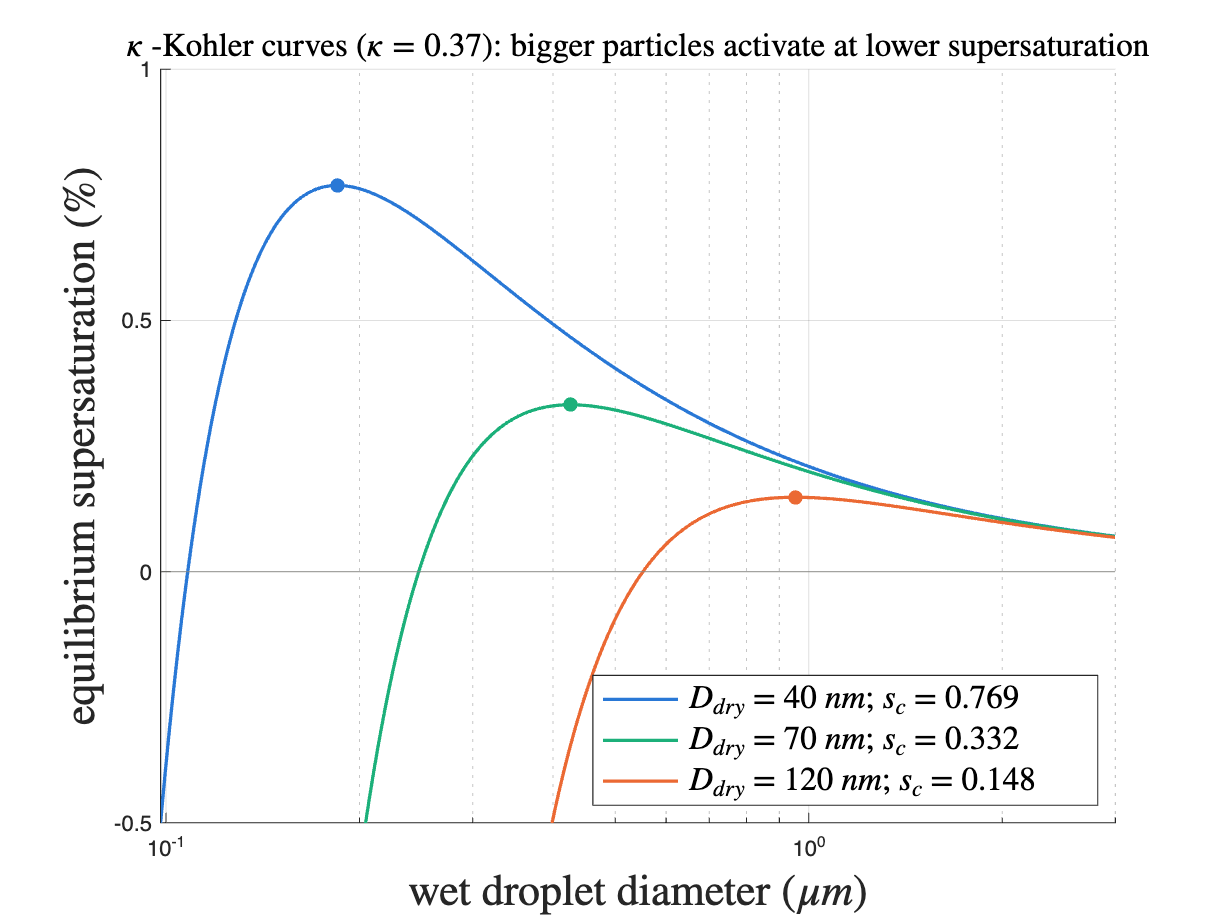

kappa_demo = 0.37;
new_figure(); hold on
dry_nm = [40 70 120];
cols = [0.16 0.47 0.84; 0.11 0.69 0.48; 0.92 0.41 0.20];
for i = 1:3
    d_wet = logspace(log10(1.02 * dry_nm(i) * 1e-9), log10(3e-6), 800);   % wet diameters (m), above the dry size
    s_pct = 100 * (kohler_saturation_ratio(d_wet, dry_nm(i) * 1e-9, kappa_demo) - 1);
    [s_peak, k] = max(s_pct);

    plot(d_wet * 1e6, s_pct, 'Color', cols(i, :), 'LineWidth', 1.5,...
        'DisplayName', ['$D_{dry}$ = ', num2str(dry_nm(i)), ' $nm$; $s_{c}$ = ', num2str(round(s_peak, 3))]);
    
    
    plot(d_wet(k) * 1e6, s_peak, 'o', 'Color', cols(i, :), 'MarkerFaceColor', cols(i, :),...
        'HandleVisibility', 'off');

end

yline(0, 'Color', [0.54 0.54 0.52], 'HandleVisibility', 'off');
set(gca, 'XScale', 'log'); ylim([-0.5 1.0]); grid on
xlabel('wet droplet diameter ($\mu m$)', 'FontSize', 20, 'Interpreter','latex'); 
ylabel('equilibrium supersaturation (\%)', 'FontSize', 20, 'Interpreter','latex'); 
title(['$\kappa$ -Kohler curves ($\kappa = ', num2str(kappa_demo), '$): ',...
    'bigger particles activate at lower supersaturation'],'FontSize', 15, 'Interpreter','latex');
legend('Location', 'southeast', 'FontSize', 15, 'Interpreter','latex');

for s = S_SET_PCT
    fprintf('s = %.1f %%  ->  critical dry diameter %5.0f nm (kappa = %.2f)\n', s, 1e9 * critical_diameter_m(s, kappa_demo), kappa_demo);
end

s = 0.1 %  ->  critical dry diameter   156 nm (kappa = 0.37)
s = 0.2 %  ->  critical dry diameter    98 nm (kappa = 0.37)
s = 0.4 %  ->  critical dry diameter    62 nm (kappa = 0.37)
s = 0.6 %  ->  critical dry diameter    47 nm (kappa = 0.37)
s = 0.8 %  ->  critical dry diameter    39 nm (kappa = 0.37)
s = 1.0 %  ->  critical dry diameter    34 nm (kappa = 0.37)


## Part 2. The posted data

The files are tab-separated, and their times are **MATLAB datenums** (`functions/read_posted_product.m`).

- `bb2743661p_34_1_supersaturation.txt` (Library: `EPCAPE_Supersaturation.txt`): the hourly retrieved supersaturations (%) for Mt. Soledad cloud events and Pier low-cloud periods.

- `bb2743661p_35_1_CCN.txt` (`epcccn2colaavgM1_DedrickCorrected.txt`): Pier CCN (cm-3) at the six setpoints, 30-min, **already multiplied by 1.57** for an inlet leak that diluted the sample (Dedrick et al. 2026, p. 1063; supplement Text S4, pp. 4-5).

- `bb2743661p_32_1_PSD_fits.txt` (`EPCAPE_PSD_fits.txt`): 5-min lognormal fits (Aitken, accumulation and coarse: N in cm-3, $D_g$ in um, $\sigma_g$), $D_{HM}$ (um) and the k-means cluster (Dedrick et al. 2026, p. 1063; supplement Texts S1-S2, p. 2).

- `bb2743661p_30_1_lowCloudPeriods.txt`: hourly flag for low-cloud periods (single-layer cloud, base and top below 3 km, coupled to the boundary layer; supplement Text S7, p. 6).

- FM-120 daily files (Dalhousie): Mt. Soledad droplet number $N_d$ for droplets of 2-50 um, 5-min (Dedrick et al. 2026, p. 1063 and Table 1 on p. 1064;  `functions/read_fm120_daily_files.m`, from the table_for_BAMS port).

**The posted supersaturation file has its** `skappa`** and** `sCCN`** columns swapped.** The next section shows the evidence and corrects the labels.

SS_POSTED = read_posted_product(fullfile(products_folder, 'bb2743661p_34_1_supersaturation.txt'));   % hourly, %
CCN_30    = read_posted_product(fullfile(products_folder, 'bb2743661p_35_1_CCN.txt'));               % 30-min, cm-3
PSD       = read_posted_product(fullfile(products_folder, 'bb2743661p_32_1_PSD_fits.txt'));          % 5-min fits
LOW_CLOUD = read_posted_product(fullfile(products_folder, 'bb2743661p_30_1_lowCloudPeriods.txt'));   % hourly flag
fprintf('supersaturation: %s .. %s (%d h); low-cloud hours: %d\n', string(SS_POSTED.time(1)), string(SS_POSTED.time(end)), ...
        height(SS_POSTED), sum(LOW_CLOUD.LowCloudPeriod == 1));

supersaturation: 15-Feb-2023 .. 15-Feb-2024 (8761 h); low-cloud hours: 334


has_ccn = any(isfinite(CCN_30{:, :}), 2);
fprintf('CCN: first data %s, last %s\n', string(CCN_30.time(find(has_ccn, 1, 'first'))), string(CCN_30.time(find(has_ccn, 1, 'last'))));

CCN: first data 23-May-2023 15:00:00, last 13-Feb-2024 23:30:00


## The swapped columns: evidence and fix

A CCN-based retrieval cannot exist before the Pier CCN counter came online on 23 May 2023. The figure's panel labels also match the posted columns the other way round (Fig. 10a $s_{CCN}$ = 0.31 ± 0.21 = posted `skappa_LowCloudPeriod`). Part 5 confirms it against an independent re-derivation of $s_{CCN}$.

names = SS_POSTED.Properties.VariableNames';
n_hours = zeros(numel(names), 1); before_ccn = n_hours; mean_std = strings(numel(names), 1); first_hour = NaT(numel(names), 1);
for i = 1:numel(names)
    v = SS_POSTED.(names{i}); ok = isfinite(v);
    n_hours(i) = nnz(ok); before_ccn(i) = nnz(ok & SS_POSTED.time < CCN_ONLINE);
    first_hour(i) = SS_POSTED.time(find(ok, 1, 'first'));
    mean_std(i) = sprintf('%.2f±%.2f', mean(v(ok)), std(v(ok)));
end
posted_columns = table(n_hours, first_hour, before_ccn, mean_std, 'RowNames', names, ...
    'VariableNames', {'hours', 'first hour', 'hours before CCN online', 'posted mean±std'})

posted_columns = 8x4 table
                                hours         first hour         hours before CCN online    posted mean±std
                                _____    ____________________    _______________________    _______________

    skappa_SoledadCloudEvent     128     03-Jun-2023 15:00:00               0                 "0.42±0.27"  
    sCCN_SoledadCloudEvent       238     12-Mar-2023 21:00:00              61                 "0.31±0.18"  
    sNd_SoledadCloudEvent        177     03-Jun-2023 15:00:00               0                 "0.06±0.05"  
    sARG00_SoledadCloudEvent     168     12-Mar-2023 21:00:00              50                 "0.03±0.02"  
    skappa_LowCloudPeriod        194     23-May-2023 22:00:00               0                 "0.31±0.21"  
    sCCN_LowCloudPeriod          316     12-Mar-2023 21:00:00              66                 "0.33±0.19"  
    sNd_LowCloudPeriod           255     23-May-2023 22:00:00               0                 "0.13±0.14"  



% Fig. 10 labels (mean ± std printed in the paper; light = low-cloud periods, dark = Soledad cloud events)
FIG10 = struct('sCCN_LowCloudPeriod', '0.31±0.21', 'sCCN_SoledadCloudEvent', '0.45±0.29', ...
               'skappa_LowCloudPeriod', '0.33±0.19', 'skappa_SoledadCloudEvent', '0.32±0.17', ...
               'sNd_LowCloudPeriod', '0.13±0.14', 'sNd_SoledadCloudEvent', '0.07±0.05', ...
               'sARG00_LowCloudPeriod', '0.1±0.06', 'sARG00_SoledadCloudEvent', '0.03±0.02');

% correct the labels: what the file calls skappa is s_CCN, and vice versa
SS = SS_POSTED;
for p = ["LowCloudPeriod", "SoledadCloudEvent"]
    SS = renamevars(SS, "skappa_" + p, "TMP_" + p);
    SS = renamevars(SS, "sCCN_" + p, "skappa_" + p);
    SS = renamevars(SS, "TMP_" + p, "sCCN_" + p);
end
assert(all(SS.time(isfinite(SS.sCCN_LowCloudPeriod)) >= CCN_ONLINE), 's_CCN before the CCN counter was online');
disp('Labels corrected: the column posted as skappa_* is now sCCN_* and vice versa.')

Labels corrected: the column posted as skappa_* is now sCCN_* and vice versa.


## Part 3. The Pier CCN spectrum, and how one hourly spectrum is built

The CCN-200 **steps through its setpoints**, about 10 min each, so a 30-min average holds only 1-3 of the 6 setpoints (table below). An hourly spectrum therefore needs a rule for the missing setpoints. The paper does not state its rule. The one in `functions/hourly_ccn_spectrum.m` reproduces the posted retrievals best (Part 4):

- average each setpoint over the hour $[t, t+1\,\mathrm{h})$;

- where a setpoint has no value in that hour, interpolate it linearly in time from the neighbouring hours, across at most `CCN_GAP_FILL_H` = 2 missing hours;

- keep only hours with all six setpoints.

**Physics and uncertainty.** Each setpoint gives one point of the aerosol's activity spectrum, the number of particles activated as a function of supersaturation (Rogers and Yau 1989, p. 95). The Pier counts are already corrected by 1.57 for dilution by an inlet leak (Dedrick et al. 2026, p. 1063; supplement Text S4, pp. 4-5). Their uncertainty is 22 ± 5 % on average and up to 60 % at 0.1-0.2 % (supplement Text S3, p. 4): the setpoints that matter most for EPCAPE's low supersaturations (Part 4).

c30 = CCN_30(CCN_30.time >= CCN_ONLINE, :);
n_set = sum(isfinite(c30{:, :}), 2);
fprintf('30-min rows by number of setpoints with data: 0: %d, 1: %d, 2: %d, 3: %d\n', ...
        nnz(n_set == 0), nnz(n_set == 1), nnz(n_set == 2), nnz(n_set == 3));

30-min rows by number of setpoints with data: 0: 2542, 1: 932, 2: 3804, 3: 5587


example_rows = c30(timerange(datetime(2023,6,1,0,0,0), datetime(2023,6,1,3,0,1)), :);
example_rows{:, :} = round(example_rows{:, :})   % the setpoints rotate through the rows

example_rows = 7x6 timetable
            time            0.1%    0.2%    0.4%    0.6%    0.8%    1.0%
    ____________________    ____    ____    ____    ____    ____    ____

    01-Jun-2023 00:00:00    153     237     NaN     NaN     NaN     NaN 
    01-Jun-2023 00:30:00    NaN     NaN     304     393     469     NaN 
    01-Jun-2023 01:00:00    NaN     NaN     NaN     NaN     NaN     496 
    01-Jun-2023 01:30:00    145     217     258     NaN     NaN     NaN 
    01-Jun-2023 02:00:00    NaN     NaN     NaN     307     362     394 
    01-Jun-2023 02:30:00    149     240     NaN     NaN     NaN     NaN 
    01-Jun-2023 03:00:00    NaN     NaN     272     338     395     NaN 



[T_CCN_H, CCN_H] = hourly_ccn_spectrum(c30.time, c30{:, :}, CCN_GAP_FILL_H);   % complete hourly spectra (cm-3)
fprintf('complete hourly spectra: %d\n', numel(T_CCN_H));

complete hourly spectra: 5184


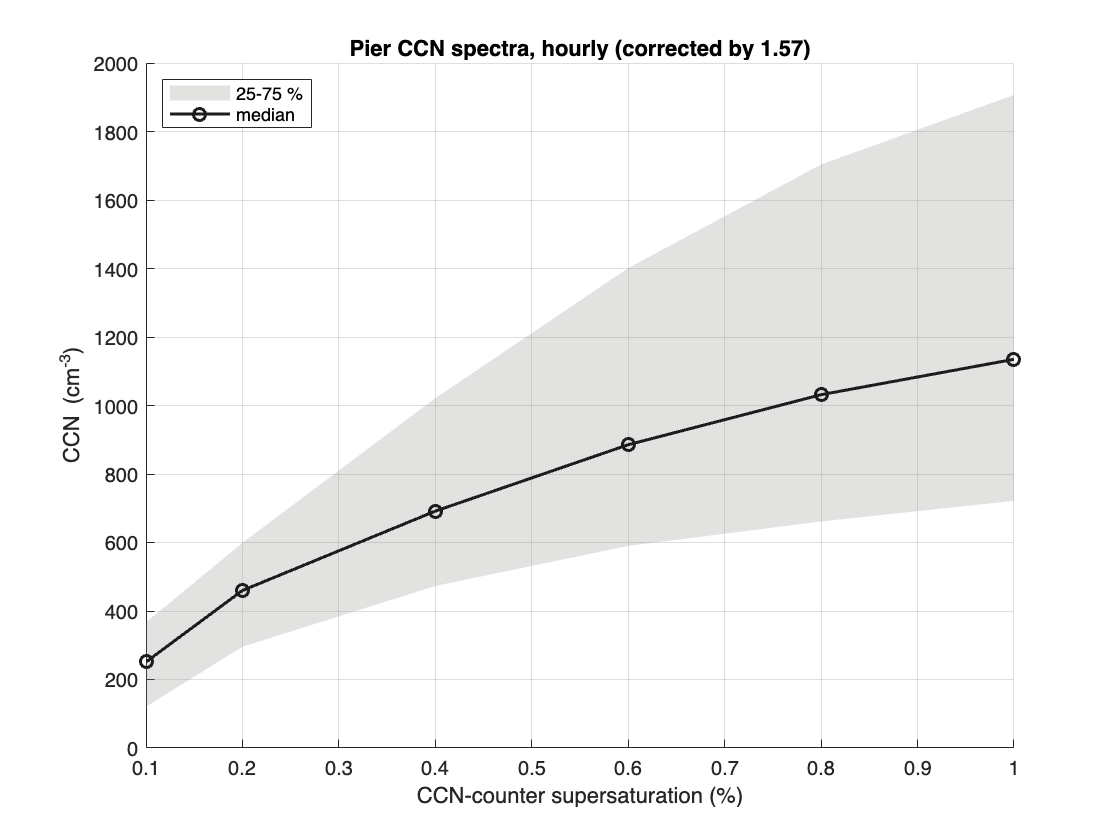


% the campaign's spectra: median and interquartile range at each setpoint
q = prctile(CCN_H, [25 50 75], 1);   % 3 x 6 (cm-3)
new_figure(); hold on
fill([S_SET_PCT fliplr(S_SET_PCT)], [q(1, :) fliplr(q(3, :))], [0.54 0.54 0.52], 'FaceAlpha', 0.25, ...
     'EdgeColor', 'none', 'DisplayName', '25-75 %');
plot(S_SET_PCT, q(2, :), 'o-', 'Color', [0.11 0.11 0.11], 'LineWidth', 1.5, 'DisplayName', 'median');
xlabel('CCN-counter supersaturation (%)'); ylabel('CCN (cm^{-3})'); grid on
title('Pier CCN spectra, hourly (corrected by 1.57)'); legend('Location', 'northwest');

## Physics check: the activity spectrum and Twomey's peak supersaturation

Rogers and Yau (1989, p. 95, eq. 6.20) approximate an activity spectrum by a power law, $N_c = C s^k$, with $s$ in percent. Typical values are $C$ = 30-300 cm-3 and $k$ = 0.3-1.0 in maritime air, and $C$ = 300-3000 cm-3 and $k$ = 0.2-2.0 in continental air (Rogers and Yau 1989, p. 95). Twomey (1959) used this form to estimate the peak supersaturation and the droplet number in an updraft of speed $U$ (Rogers and Yau 1989, pp. 95-96, eqs. 6.21-6.22; $U$ in cm/s, $C$ in cm-3, $S_{max}$ in %; written for $k$ between 0.4 and 1.0):


$$S_{max} \approx 3.6\left[\frac{1.6\times10^{-3}\,U^{3/2}}{C}\right]^{1/(k+2)}, \qquad N \approx 0.88\,C^{2/(k+2)}\left[7\times10^{-2}\,U^{3/2}\right]^{k/(k+2)}$$


The cell fits the power law to the campaign's median Pier spectrum (Part 3) and evaluates both formulas for a range of updrafts. EPCAPE's sub-cloud velocity has a median below 0.2 m/s (Dedrick et al. 2026, p. 1075). This is an independent, textbook-level check of why EPCAPE clouds have low supersaturations; Twomey's formulas are an approximation, not one of the paper's four methods (my calculation).

% fit log10(N_c) = log10(C) + k log10(s) to the median hourly spectrum (Rogers and Yau 1989, p. 95, eq. 6.20)
pfit  = polyfit(log10(S_SET_PCT), log10(q(2, :)), 1);
k_fit = pfit(1);          % slope of the activity spectrum (dimensionless)
C_fit = 10 ^ pfit(2);     % CCN activated at s = 1 % (cm-3)
fprintf('Median Pier activity spectrum: N_c = C s^k with C = %.0f cm-3 and k = %.2f\n', C_fit, k_fit);

Median Pier activity spectrum: N_c = C s^k with C = 1203 cm-3 and k = 0.65


U_ms  = [0.05 0.1 0.2 0.5 1.0]';   % updraft speeds (m/s)
U_cms = 100 * U_ms;                % Twomey's formulas use cm/s
smax_twomey_pct = 3.6 * ((1.6e-3 * U_cms .^ 1.5) / C_fit) .^ (1 / (k_fit + 2));                    % eq. 6.22 (%)
nd_twomey_cm3   = 0.88 * C_fit ^ (2 / (k_fit + 2)) * (7e-2 * U_cms .^ 1.5) .^ (k_fit / (k_fit + 2));  % eq. 6.21 (cm-3)
twomey_check = table(U_ms, round(smax_twomey_pct, 3), round(nd_twomey_cm3), ...
    'VariableNames', {'updraft U (m/s)', 'Twomey S_max (%)', 'Twomey N_d (cm-3)'})

twomey_check = 5x3 table
    updraft U (m/s)    Twomey S_max (%)    Twomey N_d (cm-3)
    _______________    ________________    _________________

         0.05               0.054                 176       
          0.1                0.08                 227       
          0.2               0.118                 293       
          0.5               0.199                 410       
            1               0.295                 528       


## Part 4. The cloud-scene retrieval: where does the CCN spectrum reach the droplet number?

Because $N_d = \mathrm{CCN}(S_{max})$ (Part 1), the cloud's effective supersaturation is the $s$ at which the hourly CCN spectrum equals the hourly droplet number (`functions/retrieve_supersaturation_pct.m`). Following the paper (Sec. 2d):

- connect the six setpoints with **straight lines**;

- below 0.1 %, draw a straight line to **0 cm-3 at 0 %**;

- above 1.0 %, extend the last segment linearly to 1.2 %;

- drop any answer above 1.2 % or below 0.

$N_d$ at Mt. Soledad comes from the FM-120: the mean of its 5-min values with LWC > 0.01 g m-3 in each hour. Cloud events are the hours where the posted file has a value. The Pier low-cloud periods use the ARM NDROP retrieval of $N_d$, which is not downloaded here, so their posted values are used as they are.

**Why the 0.1 % point matters so much.** Below 0.1 %, the spectrum is the straight line from (0, 0) to (0.1 %, CCN(0.1 %)), so


$$s_{N_d} = 0.1\,\% \times \frac{N_d}{\mathrm{CCN}(0.1\,\%)}$$


Any change to CCN(0.1 %), such as Sourita's correction, rescales every retrieval in that range by the inverse factor.

**Physical basis.** The method rests on $N_d = \mathrm{CCN}(S_{max})$ (Part 1; Rogers and Yau 1989, pp. 107-110), and observations confirm the close relation between the CCN spectrum and the resulting droplets (Rogers and Yau 1989, p. 96). In stratus the droplet concentration is roughly constant through much of the cloud, and droplets grow mainly by condensation (Rogers and Yau 1989, pp. 74-75). So a droplet number measured inside the cloud, as the FM-120 does at Mt. Soledad, still reflects the activation near cloud base (my inference). Because the droplets come from one hour of many parcels with different updrafts, the result is an *effective* supersaturation for the cloud scene, not a single parcel's $S_{max}$ (Dedrick et al. 2026, p. 1066).

**The extrapolation below 0.1 %.** The end point (0 %, 0 cm-3) agrees with the power-law spectrum $N_c = Cs^k$, which is zero at $s = 0$ (Rogers and Yau 1989, p. 95, eq. 6.20). The straight line between them is the paper's choice (Dedrick et al. 2026, pp. 1065-1066), not a physical law. A power law of slope $k$ below 0.1 % would give $s = 0.1\,\% \times (N_d/\mathrm{CCN}_{0.1})^{1/k}$; for $k$ = 0.65 and $N_d$ equal to half of CCN(0.1 %), that is 0.034 % instead of the straight line's 0.050 % (my calculation). The supplement notes that $N_d$ was often below the CCN count at 0.1 % (supplement Text S10, p. 9).

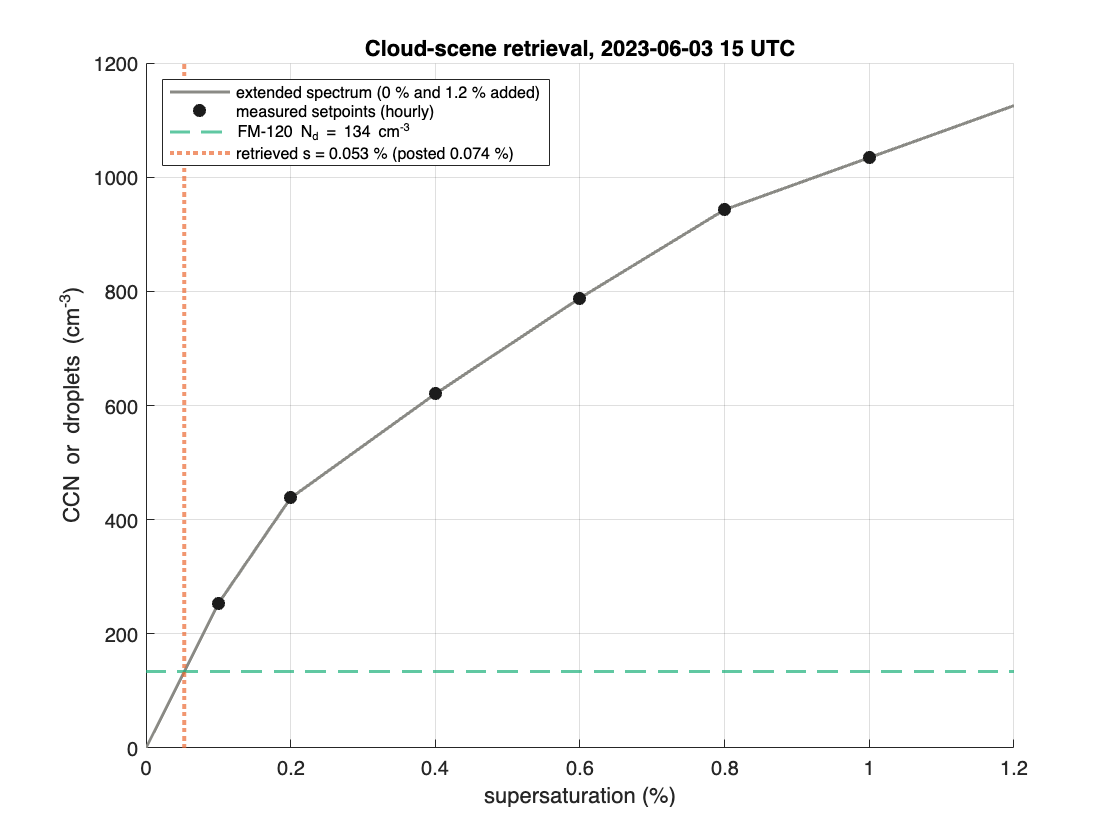

fm = read_fm120_daily_files(fm120_folder);   % 5-min FM-120 (Mt. Soledad)
nd_cloud = fm.nd_cm3;
nd_cloud(~(fm.lwc_gm3 > FM_CLOUD_LWC)) = NaN;   % in-cloud intervals only
ND_FM_H = retime(timetable(fm.time, nd_cloud, 'VariableNames', {'nd_cm3'}), 'hourly', @(x) mean(x, 'omitnan'));

% helper: the hourly spectrum at time t (row of CCN_H), or NaNs if that hour has no complete spectrum
spectrum_at = @(t) ccn_spectrum_at_hour(t, T_CCN_H, CCN_H);

% one worked example: the first Mt. Soledad cloud-event hour
posted_nd = SS(isfinite(SS.sNd_SoledadCloudEvent), 'sNd_SoledadCloudEvent');
t0 = posted_nd.time(1);
spec0 = spectrum_at(t0);
nd0 = ND_FM_H.nd_cm3(ND_FM_H.Time == t0);
s0 = retrieve_supersaturation_pct(nd0, spec0);
[s_ext0, c_ext0] = extend_ccn_spectrum(spec0);
new_figure(); hold on
plot(s_ext0, c_ext0, '-', 'Color', [0.54 0.54 0.52], 'LineWidth', 1.5, 'DisplayName', 'extended spectrum (0 % and 1.2 % added)');
plot(S_SET_PCT, spec0, 'o', 'Color', [0.11 0.11 0.11], 'MarkerFaceColor', [0.11 0.11 0.11], 'DisplayName', 'measured setpoints (hourly)');
yline(nd0, '--', 'Color', [0.11 0.69 0.48], 'LineWidth', 1.5, 'DisplayName', sprintf('FM-120 N_d = %.0f cm^{-3}', nd0));
xline(s0, ':', 'Color', [0.92 0.41 0.20], 'LineWidth', 2, 'DisplayName', ...
      sprintf('retrieved s = %.3f %% (posted %.3f %%)', s0, posted_nd.sNd_SoledadCloudEvent(1)));
xlabel('supersaturation (%)'); ylabel('CCN or droplets (cm^{-3})'); grid on
title(sprintf('Cloud-scene retrieval, %s UTC', string(t0, 'yyyy-MM-dd HH'))); legend('Location', 'northwest', 'FontSize', 8);


% every Mt. Soledad cloud-event hour, against the posted values
OURS_SND_FM = NaN(height(posted_nd), 1);
for i = 1:height(posted_nd)
    t = posted_nd.time(i);
    OURS_SND_FM(i) = retrieve_supersaturation_pct(ND_FM_H.nd_cm3(ND_FM_H.Time == t), spectrum_at(t));
end
cmp_snd = compare_to_posted(OURS_SND_FM, posted_nd.sNd_SoledadCloudEvent, 0.005, 's_Nd,FM (Mt. Soledad cloud events)');

s_Nd,FM (Mt. Soledad cloud events): re-derived 177 of 177 posted hours, r = 0.947, median difference -0.0000 %, within ±0.005 %: 77 %


## Below 0.1 %, and what a change in CCN(0.1 %) does

How many retrievals sit on the extrapolated line below 0.1 %, and the mean cloud-scene supersaturation if the CCN count at the 0.1 % setpoint were scaled. A factor of 1.0 is as posted; Sourita's correction would set the factor. For the low-cloud hours, $N_d$ (NDROP) is not downloaded, so the $N_d$ *implied* by each posted value and our spectrum, $N_d = \mathrm{CCN}(s_{posted})$, is re-retrieved with the changed CCN(0.1 %). This is exact where our spectrum equals Jeramy's.

v = SS.sNd_SoledadCloudEvent(isfinite(SS.sNd_SoledadCloudEvent));
fprintf('Mt. Soledad cloud events (FM-120): %d h; below 0.1 %%: %.0f %%; between 0.1 and 0.2 %%: %.0f %%\n', ...
        numel(v), 100 * mean(v < 0.1), 100 * mean(v >= 0.1 & v < 0.2));

Mt. Soledad cloud events (FM-120): 177 h; below 0.1 %: 83 %; between 0.1 and 0.2 %: 15 %


v = SS.sNd_LowCloudPeriod(isfinite(SS.sNd_LowCloudPeriod));
fprintf('Pier low-cloud periods (NDROP): %d h; below 0.1 %%: %.0f %%; between 0.1 and 0.2 %%: %.0f %%\n', ...
        numel(v), 100 * mean(v < 0.1), 100 * mean(v >= 0.1 & v < 0.2));

Pier low-cloud periods (NDROP): 255 h; below 0.1 %: 57 %; between 0.1 and 0.2 %: 29 %



% N_d at the Soledad cloud-event hours (FM-120) and the N_d implied at the low-cloud hours
[tf, loc] = ismember(posted_nd.time, ND_FM_H.Time);
nd_fm_t = posted_nd.time(tf); nd_fm = ND_FM_H.nd_cm3(loc(tf));
keep = isfinite(nd_fm); nd_fm_t = nd_fm_t(keep); nd_fm = nd_fm(keep);
posted_low = SS(isfinite(SS.sNd_LowCloudPeriod), 'sNd_LowCloudPeriod');
nd_low_t = NaT(0, 1); nd_low = zeros(0, 1);
for i = 1:height(posted_low)
    spec = spectrum_at(posted_low.time(i));
    if all(isfinite(spec))
        [s_ext, c_ext] = extend_ccn_spectrum(spec);
        nd_low_t(end + 1, 1) = posted_low.time(i);                                %#ok<SAGROW>
        nd_low(end + 1, 1) = interp1(s_ext, c_ext, posted_low.sNd_LowCloudPeriod(i));   %#ok<SAGROW>
    end
end
factors = [0.6 0.8 1.0 1.25 1.6]';
soledad_mean = zeros(size(factors)); lowcloud_mean = zeros(size(factors));
for f = 1:numel(factors)
    soledad_mean(f)  = mean_snd_with_scaled_ccn01(nd_fm_t, nd_fm, factors(f), T_CCN_H, CCN_H);
    lowcloud_mean(f) = mean_snd_with_scaled_ccn01(nd_low_t, nd_low, factors(f), T_CCN_H, CCN_H);
end
ccn01_sensitivity = table(factors, round(soledad_mean, 3), round(lowcloud_mean, 3), 'VariableNames', ...
    {'CCN(0.1 %) factor', 'Soledad s_Nd,FM mean (%)', 'low-cloud s_Nd,VAP mean (%)'})

ccn01_sensitivity = 5x3 table
    CCN(0.1 %) factor    Soledad s_Nd,FM mean (%)    low-cloud s_Nd,VAP mean (%)
    _________________    ________________________    ___________________________

           0.6                    0.088                         0.154           
           0.8                    0.073                         0.141           
             1                    0.061                         0.128           
          1.25                    0.049                         0.114           
           1.6                    0.037                         0.093           


## Part 5. The Hoppel-minimum CCN retrieval

Same lookup as Part 4, but the target is the **number of particles larger than the Hoppel minimum**, $N(D > D_{HM})$, the particles that activated in the recent clouds. For each lognormal mode $i$ (number $N_i$, median diameter $D_{g,i}$, geometric standard deviation $\sigma_{g,i}$):


$$N_i(D' > D) = \frac{N_i}{2}\,\mathrm{erfc}\!\left(\frac{\ln(D/D_{g,i})}{\sqrt{2}\,\ln\sigma_{g,i}}\right)$$


The Pier mode fits and $D_{HM}$ are averaged over each hour, and the three modes are summed (`functions/number_above_dhm_cm3.m`).

**Physics.** The particles larger than $D_{HM}$ are the ones that activated in recent clouds (Dedrick et al. 2026, pp. 1062 and 1065). Their number is the cumulative size distribution (Rogers and Yau 1989, p. 91, eq. 6.11) counted from $D_{HM}$ upward. For a lognormal mode, which is a normal distribution in $\ln D$, that integral is the erfc expression above (a mathematical identity). $D_{HM}$ records the highest supersaturation of an ensemble of recent cloud cycles, and the out-of-cloud number above $D_{HM}$ often exceeded the cloud-average $N_d$ by more than 250 cm-3. Both bias $s_{CCN}$ high (Dedrick et al. 2026, pp. 1074-1075).

pier_vars = {'Pier_ait_N', 'Pier_acc_N', 'Pier_coarse_N', 'Pier_ait_diam', 'Pier_acc_diam', 'Pier_coarse_diam', ...
             'Pier_ait_gsd', 'Pier_acc_gsd', 'Pier_coarse_gsd', 'Pier_DHM'};
PSD_H = retime(PSD(:, pier_vars), 'hourly', @(x) mean(x, 'omitnan'));   % hourly-mean fits and D_HM
N_ABOVE_H = number_above_dhm_cm3(PSD_H{:, 1:3}, PSD_H{:, 4:6}, PSD_H{:, 7:9}, PSD_H.Pier_DHM);

for p = ["LowCloudPeriod", "SoledadCloudEvent"]
    col = "sCCN_" + p;   % corrected label (Part 2)
    posted = SS(isfinite(SS.(col)), col);
    ours = NaN(height(posted), 1);
    for i = 1:height(posted)
        k = find(PSD_H.time == posted.time(i), 1);
        if ~isempty(k)
            ours(i) = retrieve_supersaturation_pct(N_ABOVE_H(k), spectrum_at(posted.time(i)));
        end
    end
    compare_to_posted(ours, posted.(col), 0.01, col);
end

sCCN_LowCloudPeriod: re-derived 192 of 194 posted hours, r = 0.943, median difference +0.0012 %, within ±0.01 %: 64 %
sCCN_SoledadCloudEvent: re-derived 127 of 128 posted hours, r = 0.970, median difference +0.0010 %, within ±0.01 %: 48 %


## Part 6. The Hoppel-minimum kappa retrieval

The critical supersaturation of a particle exactly at the Hoppel minimum: $s_\kappa = s_c(D_{HM}, \kappa)$ from the kappa-Kohler approximation (Petters and Kreidenweis 2007, p. 1964, eq. 10; valid for $\kappa$ above 0.2 and $s_c$ below 1 %), which is the textbook critical saturation ratio $S^*$ (Rogers and Yau 1989, p. 89, eq. 6.8) in diameter form (Part 1). $\kappa$ comes from the Pier ACSM composition (Library file `kcalc.nc`) with the volume-weighted mixing rule $\kappa = \sum_i \varepsilon_i \kappa_i$ (Petters and Kreidenweis 2007, p. 1962, eq. 7). `k``calc.nc`** is not in the local copy**, so this section uses a constant $\kappa$ = 0.37, the paper's campaign mean at the Pier (supplement Text S10, p. 8). With the hourly $\kappa$ the agreement would be closer. Because $s_\kappa \propto \kappa^{-1/2}$, a 20 % error in $\kappa$ moves $s_\kappa$ by about 10 % (my calculation).

s_kappa_ours = critical_supersaturation_pct(PSD_H.Pier_DHM * 1e-6, KAPPA_PIER);   % D_HM in um -> m
for p = ["LowCloudPeriod", "SoledadCloudEvent"]
    col = "skappa_" + p;
    posted = SS(isfinite(SS.(col)), col);
    [tf, loc] = ismember(posted.time, PSD_H.time);
    o = NaN(height(posted), 1); o(tf) = s_kappa_ours(loc(tf));
    ok = isfinite(o);
    R = corrcoef(o(ok), posted.(col)(ok));
    fprintf('%s: %d h, r = %.3f, median ours/posted = %.2f (constant kappa = %.2f; the posted values use the hourly ACSM kappa)\n', ...
            col, nnz(ok), R(1, 2), median(o(ok) ./ posted.(col)(ok)), KAPPA_PIER);
end

skappa_LowCloudPeriod: 316 h, r = 0.867, median ours/posted = 1.07 (constant kappa = 0.37; the posted values use the hourly ACSM kappa)
skappa_SoledadCloudEvent: 238 h, r = 0.922, median ours/posted = 1.07 (constant kappa = 0.37; the posted values use the hourly ACSM kappa)


## Part 7. The parcel retrieval (Abdul-Razzak & Ghan 2000)

A rising parcel cools at a rate set by the updraft $w$, which produces supersaturation, while condensation on the droplets removes it: $dS/dt = Q_1\,dz/dt - Q_2\,d\chi/dt$ (Rogers and Yau 1989, p. 106, eqs. 7.21-7.24). The supersaturation peaks when the two balance. **Abdul-Razzak et al. (1998)** and **Abdul-Razzak and Ghan (2000)** fit the peak into one formula, given the aerosol modes, $w$, and cloud-base $T$ and $p$:


$$S_{max} = \left[\sum_i \frac{1}{S_{m,i}^2}\left( f_i \left(\frac{\zeta}{\eta_i}\right)^{3/2} + g_i \left(\frac{S_{m,i}^2}{\eta_i + 3\zeta}\right)^{3/4}\right)\right]^{-1/2}$$


How the terms map onto the textbook physics:

- $\alpha$, the supersaturation produced per metre of ascent, is Rogers and Yau's  $Q_1$, and $\gamma$ is their $Q_2$ divided by the air density (Rogers and Yau 1989, p. 106, eqs. 7.23-7.24, written with $R' = R/M_a$ and $\varepsilon = M_w/M_a$; my calculation).

- $G$ is the condensational growth coefficient $1/(F_k + F_d)$ of the droplet growth law $r\,dr/dt = (S-1)/(F_k + F_d)$, set by heat conduction and vapour diffusion (Rogers and Yau 1989, pp. 102-104, eqs. 7.17-7.18; the coefficients  $K$ and $D$ are in Table 7.1, p. 103).

- $S_{m,i}$ is the critical supersaturation of mode $i$'s median particle: the peak of the Kohler curve (Rogers and Yau 1989, p. 89, eq. 6.8) with the radius-form Kelvin coefficient $A = 2M_w\sigma/(RT\rho_w)$, which is Rogers and Yau's $a$ (p. 88).

- $\eta_i \propto (\alpha w/G)^{3/2}/N_i$ is the updraft "supply" per particle: more particles give a lower $S_{max}$ (competition), and a faster $w$ a higher one, as in Twomey's formula (Rogers and Yau 1989, pp. 95-96, eq. 6.22).

The paper uses the Pier mode fits, $\kappa$ = 0.37 for both submicron modes and 0.87 for the coarse mode (supplement Text S10, p. 8), the Doppler-lidar $w_*$ (`EPCAPE_SubCloudVelocity.txt`), and INTERPSONDE cloud-base $T$ and $p$ (Dedrick et al. 2026, p. 1066). **These inputs are not local, so the posted values cannot be re-derived here.** This section compares the textbook formula (`smax_arg2000_pct.m`) with a line-by-line port of Jeramy's posted function (`smax_posted_arg2000_pct.m`) for typical EPCAPE aerosol.

**Issues in the posted** `ParcelActivation_ARG2000.m` (14 Jul 2025). It may not be the exact version behind the paper.

- *Confirmed:* the Aitken mode takes the **accumulation-mode diameter** (the Aitken block reads `mode2_param(2)`).

- *Confirmed:* $\alpha$ and $\gamma$ use molar latent heat and heat capacity in formulas written per kg. Rogers and Yau write them with $L$ in J/kg and $c_p$ in J/(kg K) (p. 106, eqs. 7.23-7.24); the check below shows the textbook form reproduces their Fig. 7.2 and the posted form does not.

- *Confirmed:* $S_m$ and $\zeta$ use the diameter-form Kelvin coefficient ($4\sigma$) with the mode **radius**. ARG2000 pairs the radius form ($2\sigma$, Rogers and Yau's $a$, p. 88) with the radius, as does the independent pyrcel implementation (Rothenberg, pyrcel).

- *Confirmed:* the code sums per-mode square roots; ARG2000 eq. 6, above, and pyrcel take the square root of the **sum**.

With typical inputs these partly cancel: the posted code gives a 5-25 % lower $S_{max}$ than the textbook formula (table below).

% typical EPCAPE Pier aerosol: the paper's Table 2, bimodal cluster; rows = coarse, accumulation, Aitken
% columns = N (m-3), D_g (m), sigma_g, kappa
MODES_BIMODAL = [ 27e6, 0.40e-6, 2.00, 0.87;
                 638e6, 0.15e-6, 1.72, 0.37;
                 371e6, 0.043e-6, 1.53, 0.37];
T_BASE_K = 285; P_BASE_PA = 95000;   % a typical coastal cloud base (illustration only)
w_ms = [0.05 0.1 0.2 0.5 1.0]';
textbook = arrayfun(@(w) smax_arg2000_pct(MODES_BIMODAL, w, T_BASE_K, P_BASE_PA), w_ms);
posted_code = arrayfun(@(w) smax_posted_arg2000_pct(MODES_BIMODAL, w, T_BASE_K, P_BASE_PA), w_ms);
arg_comparison = table(w_ms, round(textbook, 3), round(posted_code, 3), round(posted_code ./ textbook, 3), ...
    'VariableNames', {'w (m/s)', 'textbook ARG2000 (%)', 'posted MATLAB (%)', 'posted / textbook'})

arg_comparison = 5x4 table
    w (m/s)    textbook ARG2000 (%)    posted MATLAB (%)    posted / textbook
    _______    ____________________    _________________    _________________

     0.05             0.038                  0.036                0.954      
      0.1             0.057                  0.051                0.892      
      0.2             0.085                  0.071                0.836      
      0.5              0.14                  0.109                0.779      
        1             0.204                  0.153                 0.75      


fprintf('Posted s_ARG00 (hours): low-cloud %d, Soledad %d. The paper''s sub-cloud w* median is < 0.2 m/s (Sec. 5a).\n', ...
        nnz(isfinite(SS.sARG00_LowCloudPeriod)), nnz(isfinite(SS.sARG00_SoledadCloudEvent)));

Posted s_ARG00 (hours): low-cloud 246, Soledad 168. The paper's sub-cloud w* median is < 0.2 m/s (Sec. 5a).


## Checking the parcel terms against the textbook

Rogers and Yau's Fig. 7.2 (1989, p. 106) plots $Q_1$, which equals $\alpha$, falling from about 7.6 to about 5.0 (in units of $10^{-4}$ m-1) between -30 and 20 C, and $Q_2$ at 800 hPa of about 0.3 (in units of $10^3$) near 10 C (values read off the figure). The textbook form, with $L$ in J/kg and $c_p$ in J/(kg K), should reproduce these; the posted form, with molar values, should not.

g_ms2 = 9.81; Mw = 0.018; Ma = 0.02897; R = 8.314; L_v = 2.5e6; c_p = 1005.7;   % SI, per kg (textbook form)
lv_mol = 4.5e4; cp_mol = 1005.7 * 28.97e-3; Mw_p = 18.02e-3; Ma_p = 28.97e-3; R_p = 8.3144621;   % as posted
T_C = [-30 -10 0 10 20]';
T_K = T_C + 273.15;
alpha_textbook = g_ms2 * Mw * L_v ./ (c_p * R * T_K .^ 2) - g_ms2 * Ma ./ (R * T_K);            % Q1, m-1 (eq. 7.23)
alpha_posted = g_ms2 * Mw_p * lv_mol ./ (cp_mol * R_p * T_K .^ 2) - g_ms2 * Ma_p ./ (R_p * T_K);  % m-1
alpha_check = table(T_C, round(1e4 * alpha_textbook, 2), round(1e4 * alpha_posted, 2), 'VariableNames', ...
    {'T (C)', 'textbook alpha = Q1 (1e-4 m-1)', 'posted-code alpha (1e-4 m-1)'})

alpha_check = 5x3 table
    T (C)    textbook alpha = Q1 (1e-4 m-1)    posted-code alpha (1e-4 m-1)
    _____    ______________________________    ____________________________

     -30                  7.52                             4.15            
     -10                  6.33                             3.44            
       0                  5.82                             3.15            
      10                  5.38                             2.89            
      20                  4.98                             2.66            


% Q2 = rho_air * gamma at 10 C and 800 hPa (eq. 7.24)
p_800 = 80000; T_10 = 283.15;
es_10 = 611.094 * exp(17.625 * 10 / (10 + 243.04));     % Pa (Magnus formula, as in both codes)
rho_air = p_800 / (287.05 * T_10);                       % kg m-3 (ideal gas, dry air)
gamma_textbook = R * T_10 / (es_10 * Mw) + Mw * L_v ^ 2 / (c_p * p_800 * Ma * T_10);
gamma_posted = R_p * T_10 / (es_10 * Mw_p) + Mw_p * lv_mol ^ 2 / (cp_mol * p_800 * Ma_p * T_10);
fprintf('Q2 = rho_air * gamma at 10 C, 800 hPa: textbook %.2f x 1e3, posted code %.2f x 1e3 (Fig. 7.2: about 0.3 x 1e3)\n', ...
        rho_air * gamma_textbook / 1e3, rho_air * gamma_posted / 1e3);

Q2 = rho_air * gamma at 10 C, 800 hPa: textbook 0.27 x 1e3, posted code 0.11 x 1e3 (Fig. 7.2: about 0.3 x 1e3)


## Part 8. Recreating Fig. 10

Fig. 10 of the paper shows histograms (a-d) and box plots (e) of the 1-h retrievals. Light grey = Pier low-cloud periods, dark grey = Mt. Soledad cloud events. The dotted red lines mark the CCN counter's lowest and highest setpoints (0.1 and 1.0 %). This recreation uses the **posted** hourly values, with the column labels corrected (Part 2). It is saved as `figures/dedrick2026_fig10_recreated.png`.

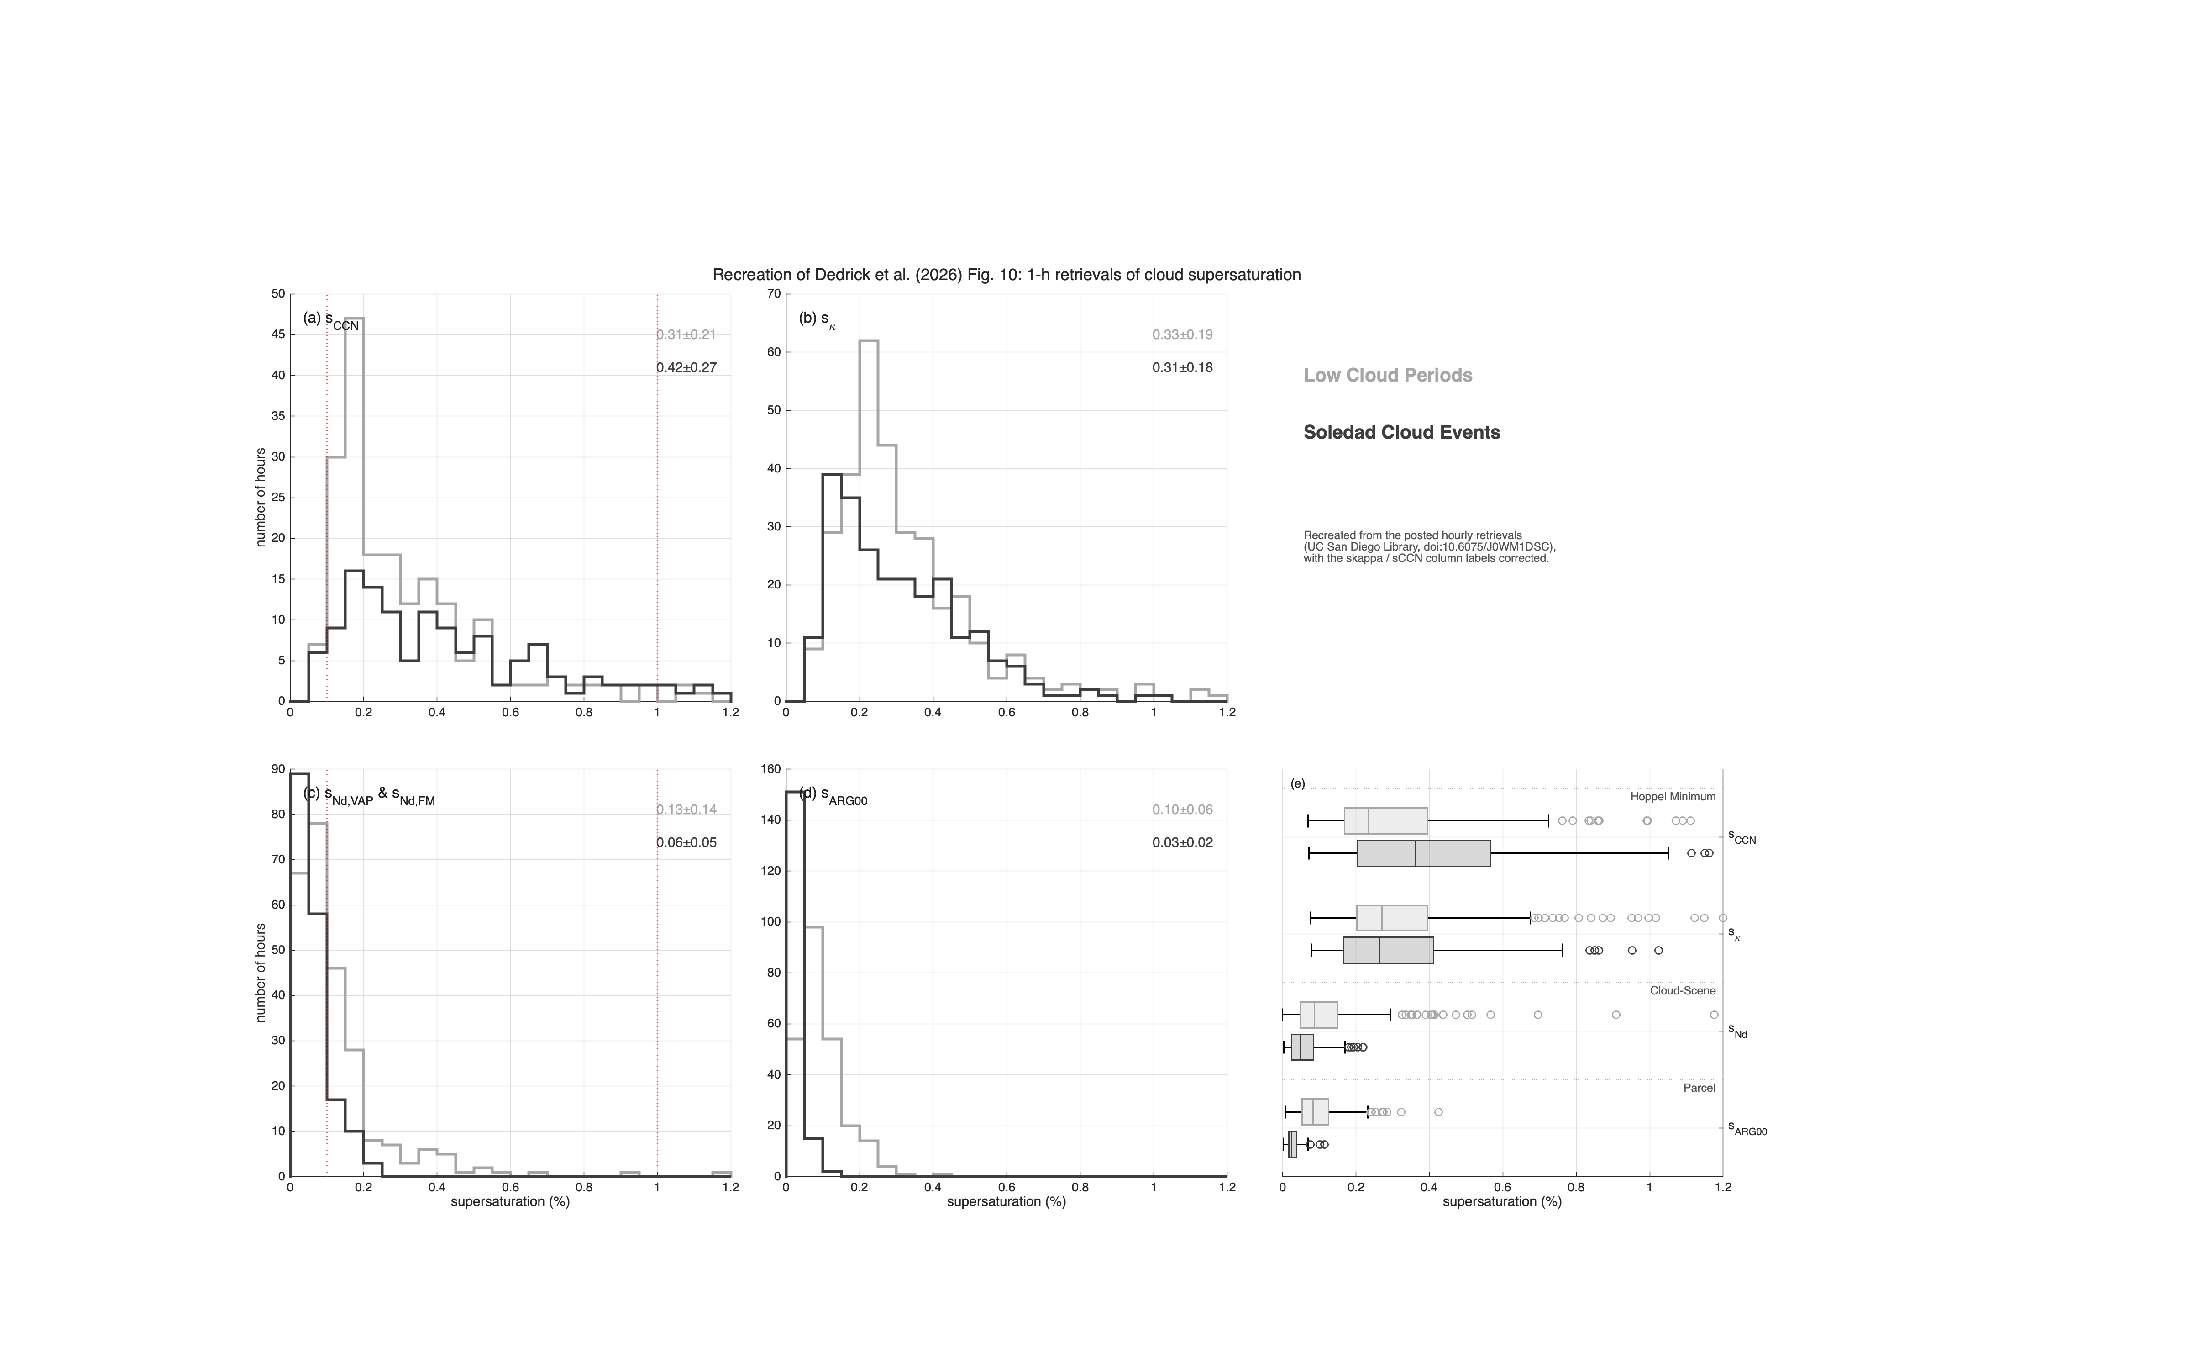

% Drawn on an INVISIBLE figure and saved, then the saved PNG is shown here. Exporting a visible
% figure has hung MATLAB for > 10 min (Live Editor and -batch runs); invisibly it takes ~1 s.
fig10_png = fullfile(fig_folder, 'dedrick2026_fig10_recreated.png');
fig10 = plot_fig10_recreation(SS, fig10_png);
close(fig10);
new_figure('Position', [100 100 1250 770]);
image(imread(fig10_png)); axis image off   % one image object: cheap to display

## The numbers behind the figure

Posted mean ± std next to the paper's Fig. 10 labels, the median, and the share of hours below 0.1 %.

method = strings(0, 1); period = strings(0, 1); hours = zeros(0, 1); posted_ms = strings(0, 1);
med = zeros(0, 1); fig_label = strings(0, 1); below01 = zeros(0, 1);
for m = ["sCCN", "skappa", "sNd", "sARG00"]
    for p = ["LowCloudPeriod", "SoledadCloudEvent"]
        v = SS.(m + "_" + p); v = v(isfinite(v));
        method(end + 1, 1) = m; period(end + 1, 1) = p; hours(end + 1, 1) = numel(v);            %#ok<SAGROW>
        posted_ms(end + 1, 1) = sprintf('%.2f ± %.2f', mean(v), std(v)); med(end + 1, 1) = median(v);   %#ok<SAGROW>
        fig_label(end + 1, 1) = FIG10.(m + "_" + p); below01(end + 1, 1) = round(100 * mean(v < 0.1));  %#ok<SAGROW>
    end
end
fig10_numbers = table(method, period, hours, posted_ms, round(med, 3), fig_label, below01, 'VariableNames', ...
    {'method', 'period', 'hours', 'posted mean ± std (%)', 'median (%)', 'Fig. 10 label', 'below 0.1 % (%)'})

fig10_numbers = 8x7 table
     method           period           hours    posted mean ± std (%)    median (%)    Fig. 10 label    below 0.1 % (%)
    ________    ___________________    _____    _____________________    __________    _____________    _______________

    "sCCN"      "LowCloudPeriod"        194         "0.31 ± 0.21"          0.233        "0.31±0.21"            4       
    "sCCN"      "SoledadCloudEvent"     128         "0.42 ± 0.27"          0.362        "0.45±0.29"            5       
    "skappa"    "LowCloudPeriod"        316         "0.33 ± 0.19"           0.27        "0.33±0.19"            3       
    "skappa"    "SoledadCloudEvent"     238         "0.31 ± 0.18"          0.265        "0.32±0.17"            5       
    "sNd"       "LowCloudPeriod"        255         "0.13 ± 0.14"          0.087        "0.13±0.14"           57       
    "sNd"       "SoledadCloudEvent"     177         "0.06 ± 0.05"          0.049        "0.07±0.05"           83       
    "sARG00" 

## Part 9. Summary and next steps

**What the methods say about EPCAPE clouds.** Coastal clouds at EPCAPE form in particle-rich air with weak updrafts (median $w_*$ below 0.2 m/s; Dedrick et al. 2026, p. 1075). Many CCN compete for the vapour (Rogers and Yau 1989, p. 89), and a weak updraft produces little supersaturation (Rogers and Yau 1989, pp. 95-96, eq. 6.22), so the clouds' effective supersaturation is low: about 0.05-0.1 % from the cloud-scene and parcel methods (Dedrick et al. 2026, p. 1075). Twomey's textbook estimate with the measured spectrum agrees in magnitude (Physics check after Part 3). The Hoppel-minimum methods give about 0.3 %, because $D_{HM}$ records the highest supersaturation of recent cloud cycles, not the typical one (Dedrick et al. 2026, pp. 1074-1075).

**Why Sourita's correction matters (Part 4).** Most cloud-scene retrievals lie *below* the lowest CCN setpoint (0.1 %), on the straight line from (0, 0) to (0.1 %, CCN(0.1 %)) (Dedrick et al. 2026, pp. 1065-1066; supplement Text S10, p. 9). There the retrieved supersaturation is inversely proportional to the CCN count at 0.1 %, the least certain setpoint (supplement Text S3, p. 4). $s_\kappa$ and $s_{ARG00}$ do not use the CCN counter, so they would not change.

**Files to get from the Library item (doi:10.6075/J0WM1DSC) to complete the re-derivation**

- `kcalc.nc`: hourly Pier $\kappa$, for $s_\kappa$ (Part 6) and $s_{ARG00}$;

- `EPCAPE_SubCloudVelocity.txt`: $w_*$, for $s_{ARG00}$ (Part 7);

- `SMPS_APS_merged.nc`: the measured merged size distributions (Part 5 check);

- `EPCAPE_Pier_CCNclosure_and_correction.zip`: Jeramy's MATLAB code for the 1.57 correction;

- ARM: the NDROP VAP ($N_d$ for the low-cloud periods) and INTERPSONDE (cloud-base $T$, $p$).

**Questions for Jeramy and Veronica**

- The posted `EPCAPE_Supersaturation.txt` has `skappa` and `sCCN` swapped. Can the Library file be corrected?

- How were missing CCN setpoints filled within an hour (Part 3)?

- Was the posted `ParcelActivation_ARG2000.m` the version used for the paper? Its four issues (Part 7) change $S_{max}$ by 5-25 % for typical inputs.

- Sourita's correction: is it a new factor for the 0.1 % CCN count that replaces or adds to 1.57, or a correction of the setpoint itself?

## Bibliography

- Abdul-Razzak, H., S. J. Ghan, and C. Rivera-Carpio, 1998: A parameterization of aerosol activation: 1. Single aerosol type. *J. Geophys. Res.*, 103, 6123-6131.

- Abdul-Razzak, H., and S. J. Ghan, 2000: A parameterization of aerosol activation: 2. Multiple aerosol types. *J. Geophys. Res.*, 105, 6837-6844, doi:10.1029/1999JD901161.

- Dedrick, J. L., A. Osawa, L. M. Russell, M. A. Miller, L. Robinson, R. Chang, A. S. Williams, V. Z. Berta, E. Ravichandran, M. Petters, M. J. Wheeler, S. Han, C. N. Pelayo, N. Maneenoi, D. Lubin, J. Uin, O. Enekwizu, M. Zawadowicz, O. Mayol-Bracero, and C. H. Twohy, 2026: Quantitative estimates of upwind and on-site particle scavenging and retrieved cloud supersaturations from urban coastal stratocumulus during EPCAPE. *J. Atmos. Sci.*, 83, 1061-1082, doi:10.1175/JAS-D-26-0004.1. Supplemental material: doi:10.1175/JAS-D-26-0004.s1 (cited as "supplement", with the page numbers of the supplement PDF).

- Dedrick, J. L., 2024: `kappakohler`. MATLAB function, GitHub,  `https://github.com/jdedrick95/kappakohler` (accessed 19 Oct 2026). The basis of this script's kappa-Kohler functions.

- Dedrick, J. L., 2025: `ParcelActivation_ARG2000`. MATLAB function, GitHub,  `https://github.com/jdedrick95/ParcelActivation_ARG2000` (accessed 19 Oct 2026). The basis of this script's parcel functions.

- Dedrick, J. L., 2025: `EPCAPE_Pier_CCNclosure_and_correction.m` and  `EPCAPE_Pier_kappa4CCN.mat`. MATLAB script and data in the Library item doi:10.6075/J0WM1DSC. They produced the 1.57 correction in the posted Pier CCN; not used in this script yet.

- Hoppel, W., G. Frick, and R. Larson, 1986: Effect of nonprecipitating clouds on the aerosol size distribution in the marine boundary layer.  *Geophys. Res. Lett.*, 13, 125-128, doi:10.1029/GL013i002p00125.

- Maneenoi, N., V. Berta, A. Osawa, S. Han, J. L. Dedrick, and L. M. Russell: Aerosol Quantification Products at Mt. Soledad and Scripps Pier during EPCAPE 2023-24. UC San Diego Library Digital Collections, doi:10.6075/J0WM1DSC (accessed 19 Oct 2026). The input data of this script.

- Petters, M. D., and S. M. Kreidenweis, 2007: A single parameter representation of hygroscopic growth and cloud condensation nucleus activity. *Atmos. Chem. Phys.*, 7, 1961-1971, doi:10.5194/acp-7-1961-2007.

- Robinson, L., and R. Chang (Dalhousie University): FM-120 fog monitor 5-min averages, Mt. Soledad, EPCAPE (see `readme_FM120.md` in the data folder).

- Rogers, R. R., and M. K. Yau, 1989: *A Short Course in Cloud Physics.* 3rd ed. International Series in Natural Philosophy, Vol. 113. Butterworth-Heinemann (Elsevier). Page numbers are the book's printed page numbers.

- Rothenberg, D.: pyrcel, an adiabatic cloud parcel model,  `pyrcel/activation/_arg2000.py` ([https://github.com/darothen/pyrcel](https://github.com/darothen/pyrcel), accessed 19 Oct 2026). Used only to cross-check the ARG2000 equation forms.

- Russell, L. M., and coauthors, 2023: Aerosol Microphysics and Chemical Measurements at Mt. Soledad and Scripps Pier during the Eastern Pacific Cloud Aerosol Precipitation Experiment (EPCAPE) from February 2023 to February 2024. UC San Diego Library Digital Collections, doi:10.6075/J0NG4QT4.

- Twomey, S., 1959: The nuclei of natural cloud formation: the supersaturation in natural clouds and the variation of cloud droplet concentration.  *Geofis. Pura e Appl.*, 43, 243-249. Cited through Rogers and Yau (1989, pp. 95-96).